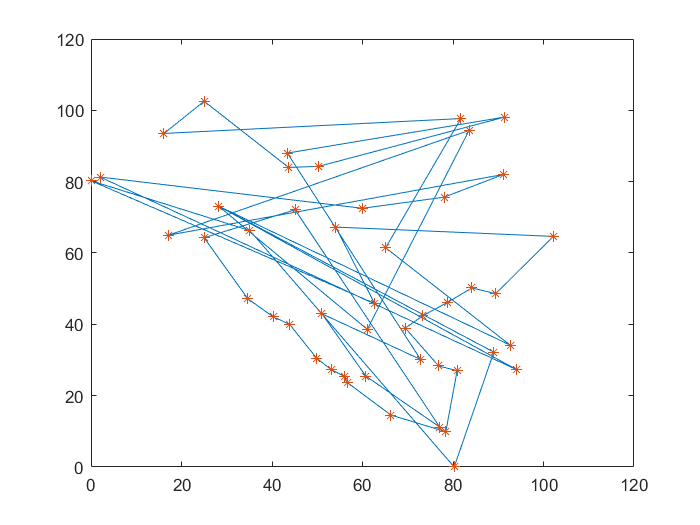

%Optimization of Travelling Salesman Problem

clc; 
close all; 
clear all

a = textread('D:\Rajat Raj\Desktop\4th SEM Notes\MM_EL\cities50.txt');

for i=1:500
    x(i,:)=randperm(50);
end
for generation = 1:300      %population size

%Forming distance matrix

for j=1:50
    for i=1:50
    y(i,j)=sqrt((a(j,1)-a(i,1))^2 + (a(j,2) - a(i,2))^2);
    end
end

%Calculating fitness for parents

for j=1:500
    sum=y(x(j,50),x(j,1));
    for i=1:49
    sum = y(x(j,i), x(j,i+1))+ sum;    
    end
    x(j,51)=sum;
end
x=sortrows(x,16);

%Crossover

w = randperm(400); 
t = randperm(50);

for i=1:200
    c1 = zeros (1,50);
    c2=c1;
    f = x(w(2*i-1), 1:50); 
    l = x(w(2*i), 1:50);

    c1(1,t(1:24)) = f(1, t(1:24));
    c2(1,t(1:24)) = l(1, t(1:24));

m1=1;
p1=2;
[s1 d1] = find(c1==0);
for j=1:50
    for k =1:50
        if (c1(k)==l(j))
          p1=1;
        end
        end
    if (p1~=1)
      c1(d1(m1))=l(j); 
      m1=m1+1;
    else
        p1=2;
    end
end

m2=1;
p2=2;
[s2 d2] = find (c2==0);
for j=1:50
    for k =1:50
        if (c2(k)==f(j))
          p2=1;
        end
    end
        if (p2~=1)
          c2(d2(m2))=f(j); 
          m2=m2+1;
        else
            p2=2;
        end
end

child1 = c1;
child2 = c2;
x(500+2*i-1,1:50) = child1;
x(500+2*i,1:50) = child2;
end

for j=1:900
    sum = y(x(j,50), x(j,1)); 
    for i=1:16
    sum = y(x(j,i),x(j,i+1))+sum;
    end
    x (j,51)=sum;
end
x=sortrows(x,51);

x = x(1:500,:);

    q= x(:,1:51); 
    q(:,51) = x(:,1);

%plotting the path of each iteration

figure (1);
title('Travelling Salesman Problem');
plot(y(q(1,1:51),1),y(q(1,1:51),2),y(q(1,1:51),1),y(q(1,1:51),2),'*');



end